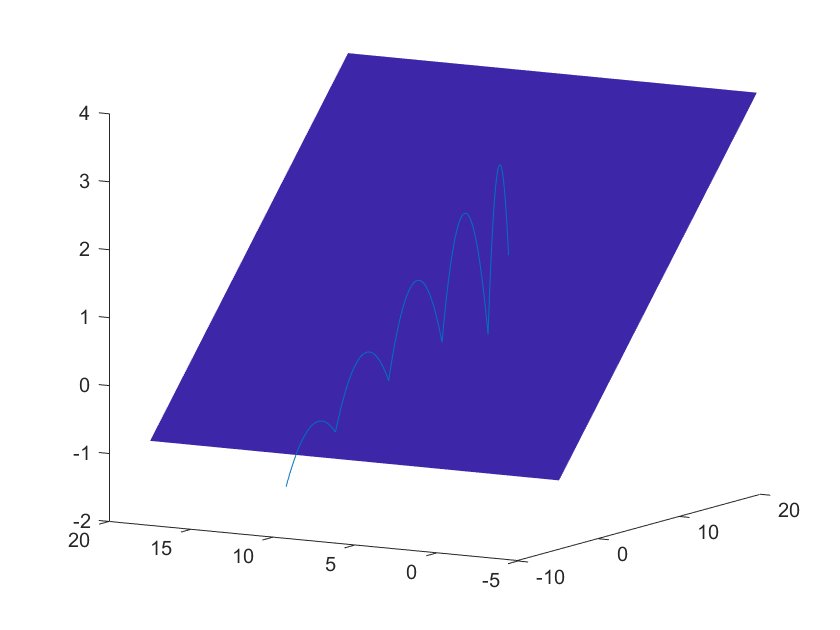

nBounces = 5;
timeout = 10; % seconds
coeff_restitution = 0.8; % unitless
g = 9.80; % m/s^2

p_0 = [1, 1, 2];
v_0 = [2, 2, 5];

origin = [0; 0; 0];
normal = [-0.2; 0; 1];

clf; hold on;

[T, States, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], coeff_restitution, origin, normal, g);
plot3(States(:, 1), States(:, 2), States(:, 3));
view(3);

parallel = null(normal.');
p1 = parallel(:, 1);
p2 = parallel(:, 2);

Xbounds = [-5, 20];
Ybounds = [-5, 20];

[a, b] = meshgrid(Xbounds, Ybounds);
X = p1(1) * a + p2(1) * b + origin(1);
Y = p1(2) * a + p2(2) * b + origin(2);
Z = p1(3) * a + p2(3) * b + origin(3);

s = surf(X, Y, Z);
s.FaceColor = 'g';
shading flat